## Create Environment 

Scenario = uavScenario("UpdateRate",100,"ReferenceLocation",[0 0 0]);
InitialPosition = [0 0 -1];
InitialOrientation = [0 0 0];
platUAV = uavPlatform("UAV",Scenario, ...
                      "ReferenceFrame","NED", ...
                      "InitialPosition",InitialPosition, ...
                      "InitialOrientation",eul2quat(InitialOrientation));
updateMesh(platUAV,"quadrotor",{1.2},[0 0 1],eul2tform([0 0 pi]));
%load('FirstMap.mat')
%Visualize Map
%show3D(Scenario);
%legend("Start Position","Obstacles")
%title("3D Drone Racing Course Environment")

## Second Map

%Course Geometry
%Bridges
BridgePositions = [20 5; 40 0; 60 10; 35 25];
BridgeAngles = [135 45 0 135];
BridgeLength = 6;
BridgeWidth  = 1;
BridgeHeight = 6;
DeckThickness = 1;
SupportHeight = BridgeHeight;
SupportWidth  = 1;
% NEW: Specify which bridges are ladders (1 = ladder, 0 = regular)
BridgeIsLadder = [1 0 0 0];   % First bridge is a ladder

%Poles 
PolePositions = [52 17; 55 22; 52 27; 55 32];
poleHeight = 8;
poleRadius = 0.2;

%Walls
WallPositions = [];
wallHeight = 8;
wallThickness = 0.3;


%Cubes
CubePositions = [45 10];
CubeSize = [7 7 7]; % width, depth, height (m)

%Tilted Walls (Diagonal Obstacles)
TiltWallCenters = [31 5];
TiltWallLength = [8];
TiltWallHeight = [10];
TiltAngle = [45]; % degrees from ground


%Set Waypoints
Waypoints = [InitialPosition; 5 20 -3; 0 40 -3; 10 60 -3; 4 45 -3; 10 53 -3; 19 53.5 -3; 24 53.5 -3; 29 53.5 -3; 25 35 -3; 5 20 -10; InitialPosition];


## Build With selected Parameters

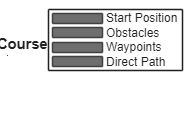

%Build Bridge
for i = 1:size(BridgePositions,1)
    baseCoords = [-BridgeLength/2, -BridgeWidth/2;
                   BridgeLength/2, -BridgeWidth/2;
                   BridgeLength/2,  BridgeWidth/2;
                  -BridgeLength/2,  BridgeWidth/2];
    theta = deg2rad(BridgeAngles(i));
    R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
    rotatedCoords = (R * baseCoords')';
    deckXY = rotatedCoords + BridgePositions(i,:);
    deckZ = [BridgeHeight, BridgeHeight + DeckThickness]; % Row vector

    % --- Draw base deck ---
    addMesh(Scenario,"polygon",{deckXY, deckZ}, [0.4 0.4 0.4]);

    % --- Add supports for the base deck ---
    supportOffsets = [-BridgeLength/2 + SupportWidth/2, 0;
                       BridgeLength/2 - SupportWidth/2, 0];
    rotatedSupportOffsets = (R * supportOffsets')';
    for s = 1:2
        sx = BridgePositions(i,1) + rotatedSupportOffsets(s,1);
        sy = BridgePositions(i,2) + rotatedSupportOffsets(s,2);
        supportXY = [sx - SupportWidth/2, sy - SupportWidth/2;
                     sx + SupportWidth/2, sy - SupportWidth/2;
                     sx + SupportWidth/2, sy + SupportWidth/2;
                     sx - SupportWidth/2, sy + SupportWidth/2];
        addMesh(Scenario,"polygon",{supportXY, [0, SupportHeight]}, [0.4 0.4 0.4]);
    end

    % =============================
    % === Ladder Extension (optional) ===
    % =============================
    if BridgeIsLadder(i) == 1
        % Top supports start above first deck
        topSupportBottomZ = SupportHeight + DeckThickness;
        topSupportTopZ = topSupportBottomZ + SupportHeight;

        % --- Add second layer of supports ---
        for s = 1:2
            sx = BridgePositions(i,1) + rotatedSupportOffsets(s,1);
            sy = BridgePositions(i,2) + rotatedSupportOffsets(s,2);
            supportXY = [sx - SupportWidth/2, sy - SupportWidth/2;
                         sx + SupportWidth/2, sy - SupportWidth/2;
                         sx + SupportWidth/2, sy + SupportWidth/2;
                         sx - SupportWidth/2, sy + SupportWidth/2];
            addMesh(Scenario,"polygon",{supportXY, [topSupportBottomZ, topSupportTopZ]}, [0.4 0.4 0.4]);
        end

        % --- Add second (upper) deck ---
        upperDeckZ = [topSupportTopZ, topSupportTopZ + DeckThickness];
        addMesh(Scenario,"polygon",{deckXY, upperDeckZ}, [0.4 0.4 0.4]);
    end
end



%Build Wall
for i = 1:size(WallPositions,1)
    cx = WallPositions(i,1);
    cy = WallPositions(i,2);
    wallXY = [cx-2, cy; cx+2, cy; cx+2, cy+wallThickness; cx-2, cy+wallThickness];
    addMesh(Scenario,"polygon",{wallXY, [0 wallHeight]}, [0.8 0.2 0.2]);
end


%Build Poles
for i = 1:size(PolePositions,1)
    cx = PolePositions(i,1);
    cy = PolePositions(i,2);
    addMesh(Scenario, "cylinder", {[cx, cy, poleRadius], [0, poleHeight]}, [1 1 0]);
end

%Build Cubes
for i = 1:size(CubePositions,1)
    cx = CubePositions(i,1);
    cy = CubePositions(i,2);
    cubeXY = [cx - CubeSize(i, 1)/2, cy - CubeSize(i, 2)/2;
              cx + CubeSize(i, 1)/2, cy - CubeSize(i, 2)/2;
              cx + CubeSize(i, 1)/2, cy + CubeSize(i, 2)/2;
              cx - CubeSize(i, 1)/2, cy + CubeSize(i, 2)/2];
    addMesh(Scenario,"polygon",{cubeXY, [0 CubeSize(i, 3)]}, [0.2 0.6 1]); % blue cube
end




%Build Tilted Walls
for i = 1:size(TiltWallCenters,1)
    cx = TiltWallCenters(i,1);
    cy = TiltWallCenters(i,2);
    theta = deg2rad(TiltAngle(i)); % small rotation variation
    R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
    baseXY = [-TiltWallLength(i)/2 -0.1; TiltWallLength(i)/2 -0.1; TiltWallLength(i)/2 0.1; -TiltWallLength(i)/2 0.1];
    wallXY = (R * baseXY')' + [cx cy];
    addMesh(Scenario,"polygon",{wallXY, [0 TiltWallHeight(i)]}, [0.5 0.2 0.7]); % purple tilted wall
end



%Build Hoops
%for i = 1:size(HoopCenters,1)
%    cx = HoopCenters(i,1);
%    cy = HoopCenters(i,2);
%    % Represent hoop as a thin cylinder
%    addMesh(Scenario, "cylinder", {[cx, cy, HoopRadius], [HoopHeight, HoopHeight + HoopThickness]}, [1 0.6 0]);
%end

%Visualtion for waypoints
for i = 2:size(Waypoints,1)
    addMesh(Scenario,"cylinder",{[Waypoints(i,2) Waypoints(i,1) 1] [0 0.1]},[1 0 0]);
end
show3D(Scenario);
hold on
plot3([InitialPosition(1,2); Waypoints(:,2)],[InitialPosition(1,2); Waypoints(:,1)],[-InitialPosition(1,3); -Waypoints(:,3)],"-g")
legend(["Start Position","Obstacles","","","Waypoints","","","Direct Path"])